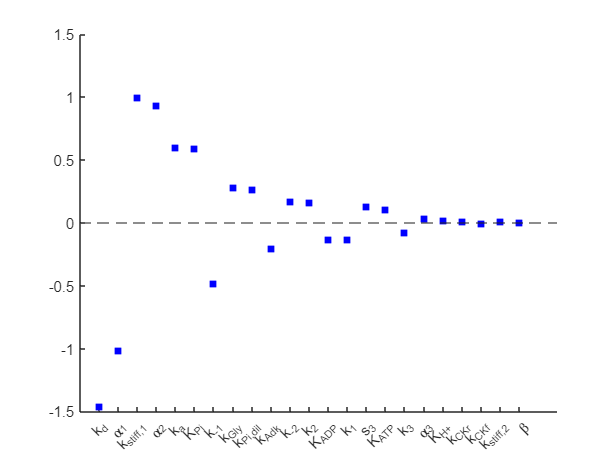

%plot sensitivities
clf;
params_table = readtable('params/params_sens.xlsx');
drop_flag = zeros(24,1);
drop_flag(16) = 1;
params_table = params_table(~drop_flag,:);
params = params_table.Parameter;
sens_force = readtable('../raw_data/Local_sens_Force.xlsx');
sens_force=sens_force(~drop_flag,:);
[~,I]=sort(abs(sens_force.c240),'descend');
sens_c240_sort=sens_force.c240(I);
scatter(1:1:23,sens_c240_sort,"blue","square","filled");
ylim([-1.5,1.5]);
yline(0,'--');
ax = gca;
ax.XTick = 1:1:23;
ax.XTickLabels = params(I);

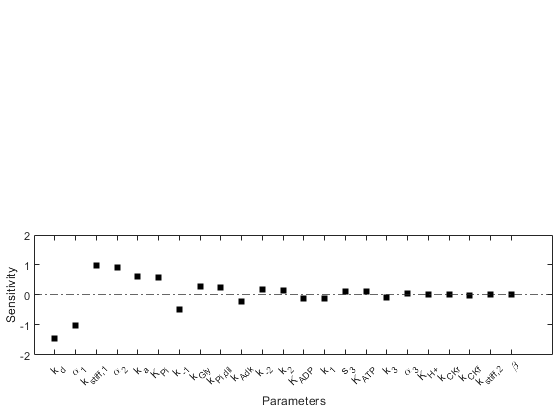

figure(7);clf;
scatter(1:1:23,sens_c240_sort,30,"black","square","filled"); hold on;box on;
%xlim([0 250]);
ylim([-2 2]);
xlabel('Parameters');
ylabel('Sensitivity');
set(gca,'Unit','Inches')
yline(0,'-.');
ax=gca;
ax.XTick = 1:1:23;
ax.XTickLabels = params(I);
ax.TickLabelInterpreter = "tex";
set(gca,'Unit','Inches')
p = get(gca,'Position');
set(gca,'Unit','Inches','Position',[p(1)-0.4 p(2) 5.4 1.25]);
exportgraphics(figure(7),fullfile(pwd,'figure_7_subplots','figure_7_a.pdf'),'BackgroundColor','w','Resolution',300,'ContentType','vector');